#  4D Sight CV Engineer-Task

## Read the Input Image Sequence

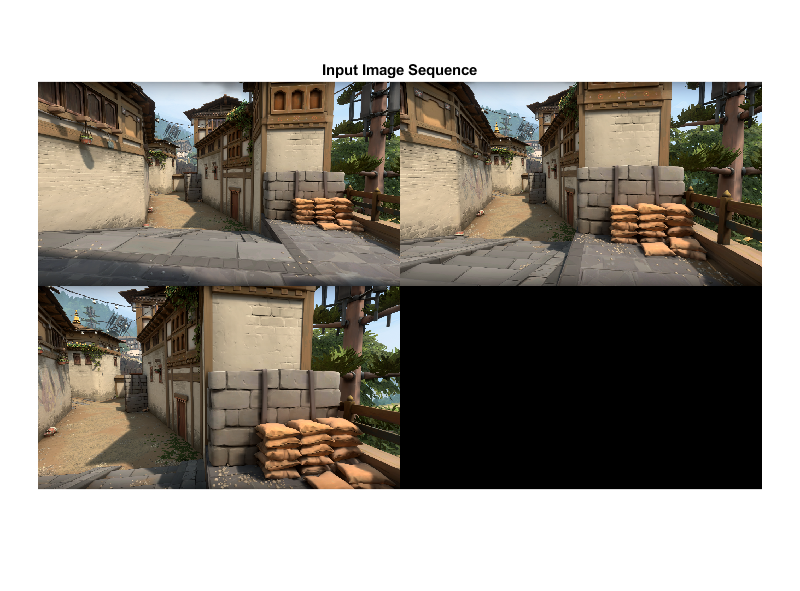

imds = imageDatastore(pwd);

% Display the images.
figure
montage(imds.Files, 'Size', [2, 2]);

% Convert the images to grayscale.
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    I = readimage(imds, i);
    images{i} = im2gray(I);
end

title('Input Image Sequence');

## Estimate Camera Parameters

Using the given 2D-3D correspondences, I tried to estimate the intrinsic matrix of the camera. 

vr2d = readNPY('vr2d.npy');
vr2d = [vr2d(:,:,1) vr2d(:,:,2)];
vr3d = readNPY('vr3d.npy');
vr3d = [vr3d(:,:,1) vr3d(:,:,2) vr3d(:,:,3)];
camMatrix = double(estimateCameraMatrix(vr2d,vr3d));
[K,~,ImC] = Pdecomp(transpose(camMatrix));
IntrinsicMatrix = K';
IntrinsicMatrix = IntrinsicMatrix/(IntrinsicMatrix(3,3))

IntrinsicMatrix =   770.8186         0         0
   -6.7482  773.5763         0
  957.6397  537.5761    1.0000



radialDistortion = [0 0 0];
cameraParams = cameraParameters('IntrinsicMatrix',IntrinsicMatrix,'RadialDistortion',radialDistortion, 'ImageSize', [1920, 1080]); 

The estimated intrinsic matrix has cx as 960 and cy as 540 which are consistent with the given parameters.

## Create a View Set Containing the First View

% Get intrinsic parameters of the camera
intrinsics = cameraParams.Intrinsics;

images = imageDatastore(pwd);
I = readimage(images, 1);

border = 4;
roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border];
prevPoints   = detectSURFFeatures(rgb2gray(I), 'NumOctaves', 8, 'ROI', roi);

prevFeatures = extractFeatures(rgb2gray(I), prevPoints, 'Upright', true);

% Create an empty imageviewset object to manage the data associated with each
% view.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
viewId = 1;
vSet = addView(vSet, viewId, rigid3d, 'Points', prevPoints);

## Add the Rest of the Views

for i = 2:3
    I = readimage(images, i);
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(rgb2gray(I), 'NumOctaves', 8, 'ROI', roi);
    currFeatures = extractFeatures(rgb2gray(I), currPoints, 'Upright', true);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        'MaxRatio', .7, 'Unique',  true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
    
    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relativeOrient, relativeLoc, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    
    prevPose = poses(vSet, i-1).AbsolutePose;
    relPose  = rigid3d(relativeOrient, relativeLoc);
        
    currPose = rigid3d(relPose.T * prevPose.T);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, 'Points', currPoints);

    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, i-1, i, relPose, 'Matches', indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-D world points and camera poses.
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
        tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
        'PointsUndistorted', true);

    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end

## Display Camera Poses

Display the refined camera poses and 3-D world points.

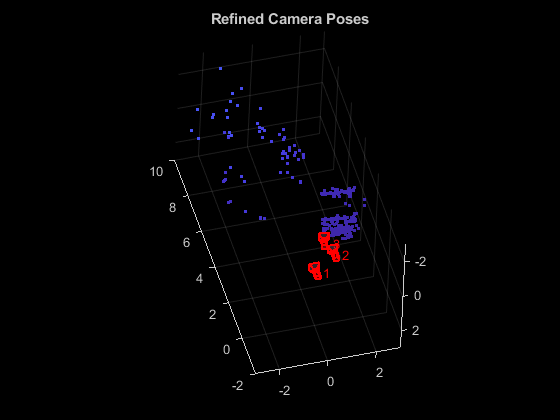

% Display camera poses.
camPoses = poses(vSet);
figure;
plotCamera(camPoses, 'Size', 0.2);
hold on

% Exclude noisy 3-D points.
goodIdx = (reprojectionErrors < 5);
xyzPoints = xyzPoints(goodIdx, :);

% Display the 3-D points.
pcshow(xyzPoints, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-3, loc1(1)+3]);
ylim([loc1(2)-3, loc1(2)+3]);
zlim([loc1(3)-2, loc1(3)+10]);
camorbit(0, 0);

title('Refined Camera Poses');

## Compute Dense Reconstruction

Go through the images again. This time detect a dense set of corners.

% Read and undistort the first image
I = readimage(images, 1);

% Detect corners in the first image.
prevPoints = detectMinEigenFeatures(rgb2gray(I), 'MinQuality', 0.001);

% Create the point tracker object to track the points across views.
tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 6);

% Initialize the point tracker.
prevPoints = prevPoints.Location;
initialize(tracker, prevPoints, I);

% Store the dense points in the view set.

vSet = updateConnection(vSet, 1, 2, 'Matches', zeros(0, 2));
vSet = updateView(vSet, 1, 'Points', prevPoints);

% Track the points across all views.
for i = 2:numel(images)
    % Read and undistort the current image.
    I = undistortImage(images{i}, intrinsics); 
    
    % Track the points.
    [currPoints, validIdx] = step(tracker, I);
    
    % Clear the old matches between the points.
    if i < numel(images)
        vSet = updateConnection(vSet, i, i+1, 'Matches', zeros(0, 2));
    end
    vSet = updateView(vSet, i, 'Points', currPoints);
    
    % Store the point matches in the view set.
    matches = repmat((1:size(prevPoints, 1))', [1, 2]);
    matches = matches(validIdx, :);        
    vSet = updateConnection(vSet, i-1, i, 'Matches', matches);
end

% Find point tracks across all views.
tracks = findTracks(vSet);

% Find point tracks across all views.
camPoses = poses(vSet);

% Triangulate initial locations for the 3-D world points.
xyzPoints = triangulateMultiview(tracks, camPoses,...
    intrinsics);

% Refine the 3-D world points and camera poses.
[xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(...
    xyzPoints, tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
    'PointsUndistorted', true);

## Display Dense Reconstruction

Display the camera poses and the dense point cloud.

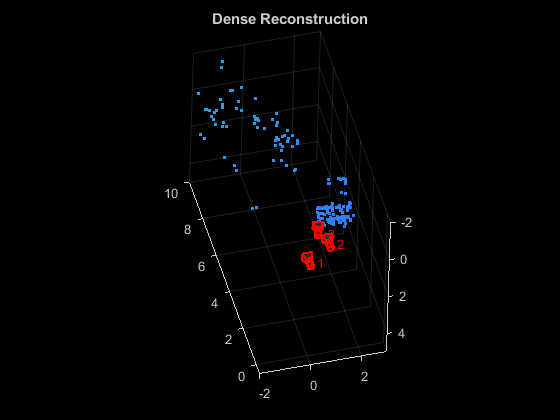

% Display the refined camera poses.
figure;
plotCamera(camPoses, 'Size', 0.2);
hold on

% Exclude noisy 3-D world points.
goodIdx = (reprojectionErrors < 5);

% Display the dense 3-D world points.
pcshow(xyzPoints(goodIdx, :), 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-2, loc1(1)+3]);
ylim([loc1(2)-2, loc1(2)+5]);
zlim([loc1(3)-0.5, loc1(3)+10]);
camorbit(0, 0);

title('Dense Reconstruction');